# MIMO Channel Estimation with interpolation

## Steps:

- Load the dataset: LS estimated channel at the pilot location, and the actual MIMO channel

- Split them into train, validation and test set

- Split them into real and imag parts

- Interpolate the Input data to match the size of output

- Save the weights and simulate to compare it with LS and MMSE techniques

### Load the dataset:

data_input = load('combined_data.mat');
data_output = load('combined_labels.mat');

### 2. Split into train, validation and test 

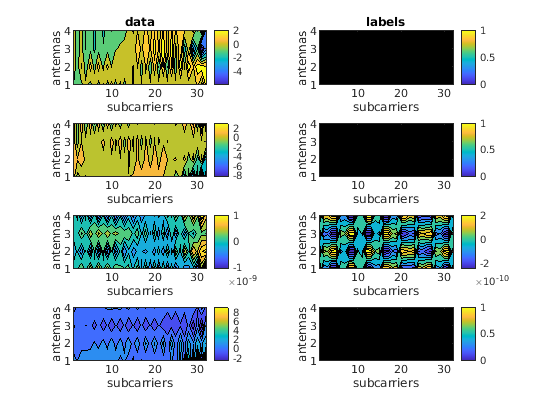

% Taking Nant = 4
Nant = size(data_input.combined_data{3,1},1);
Ncarr = size(data_output.combined_labels{3,1},2);
pilot_cols = 1:4:16;
Nuser = size(data_input.combined_data{3,1},3);
data_input2 = zeros(Nant,Ncarr,Nuser);
for i=1:Nuser
    data_input2(:,:,i) = pilot_interpolate(data_input.combined_data{3,1}(:,:,i),pilot_cols,Nant,Ncarr);
end
train_data = zeros(Nant,2*Ncarr,30000); 
train_label= zeros(Nant,2*Ncarr,30000);
val_data = zeros(Nant,2*Ncarr,1500); 
val_label = zeros(Nant,2*Ncarr,1500); 
%test_data = zeros(Nant,2*Ncarr,1500);
%test_label = zeros(Nant,2*Ncarr,1500);
real_pos = 1:2:32;
train_data(:,real_pos,:) = real(data_input2(:,:,1:30000));
train_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,1:30000));
val_data(:,real_pos,:) = real(data_input2(:,:,30001:31500));
val_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,30001:31500));
%test_data(:,real_pos,:) = real(data_input2(:,:,31501:33000));
%test_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,31501:33000));

train_data(:,real_pos+1,:) = imag(data_input2(:,:,1:30000));
train_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,1:30000));
val_data(:,real_pos+1,:) = imag(data_input2(:,:,30001:31500));
val_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,30001:31500));
%test_data(:,real_pos+1,:) = imag(data_input2(:,:,31501:33000));
%test_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,31501:33000));

plot_random_samples(train_data,train_label,'contour','training_data.png');

### 3. Training the network

layers_1 = [...
        imageInputLayer([Nant 2*Ncarr 1],'Normalization','none','Name','Input')
        convolution2dLayer(9,64,'Padding','same','Name','cnn1')
        reluLayer('Name','reLu1')
        convolution2dLayer(1,32,'Padding','same','Name','cnn2')
        reluLayer('Name', 'reLu2')
        convolution2dLayer(5,1,'Padding','same','Name','cnn3')
        %reluLayer('Name','reLu3')...,
        ];

lgraph = layerGraph(layers_1);
layers_dn = dncnn_layers();
lgraph = addLayers(lgraph,layers_dn);
lgraph = connectLayers(lgraph,'cnn3','reLu3');
lgraph = connectLayers(lgraph,'reLu3','add_1/in2');
layers_2 = lgraph.Layers;

batchSize = 200;
valFrequency = 1;
    
    options = trainingOptions('adam', ...
    'ExecutionEnvironment','cpu',...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MiniBatchSize',batchSize, ...
    'ValidationData',{val_data, val_label}, ...
    'ValidationFrequency',valFrequency, ...
    'ValidationPatience',5);
    
    [mimo_net,mimo_trainingInfo] = trainNetwork(train_data, ...
                                          train_label,layers_2,options)
                                      

### 4. Simulate and Compare with MMSE

snr = 0:4:40; %SNR in db
test_label = (data_output.combined_labels{3,1}(:,:,31501:33000));
pilot_angles = linspace(0, pi/2,length(pilot_cols));
pilot = exp(1j*pilot_angles);
pilot_channel = data_output.combined_labels{3,1}(:,pilot_cols,31501:33000);
test_label_dl = zeros(Nant,2*Ncarr,1500);
test_label_dl(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,31501:33000));
test_label_dl(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,31501:33000));
test_data_dl = zeros(Nant,2*Ncarr);
LS = [];
MMSE =[];
DL = [];
for snrdb=snr
    ls_rmse = 0;
    mmse_rmse = 0;
    dl_rmse = 0;
    for i=1:1500
        Pr_avg = norm(abs(pilot_channel(:,:,i)))^2;
        SNR    = 10^(.1*snrdb);
        Pn     = (Pr_avg/SNR)/2;
        rec = pilot_channel(:,:,i).*pilot;
        rec = rec + sqrt(Pn)*randn(size(rec,1), size(rec,2)) +...
        1i*sqrt(Pn)*randn(size(rec,1), size(rec,2)); % Add noise;
       
        [H_est_mmse,H_est_ls] = mimo_mmse_ls(Ncarr,Nant,Rec,pilot,pilot_channel(:,:,i),pilot_cols);
        test_data_dl(:,real_pos) = real(rec);
        test_data_dl(:,real_pos+1) = imag(rec);
        H_est_dl = predict(mimo_net,test_data_dl);
        dl_rmse =  dl_rmse + sqrt(mean((H_est_dl - test_label_dl(:,:,i)).^2));
        ls_rmse = ls_rmse + sqrt(mean((H_est_ls - test_label(:,:,i)).^2));
        mmse_rmse = mmse_rmse + sqrt(mean((H_est_mmse - test_label(:,:,i)).^2));
        
        
    end
    LS = [LS ls_rmse/1500];
    MMSE = [MMSE mmse_rmse/1500];
    DL = [DL dl_rmse/1500];
end

figure1 = figure
plot(snr,LS,snr,MMSE,snr,DL)
xlabel('SNR in dB')
ylabel('RMSE')
title('Comparison of DL, MMSE and LS')
legend('LS','MMSE','DL')
savefig(figure1,'comparison.png')